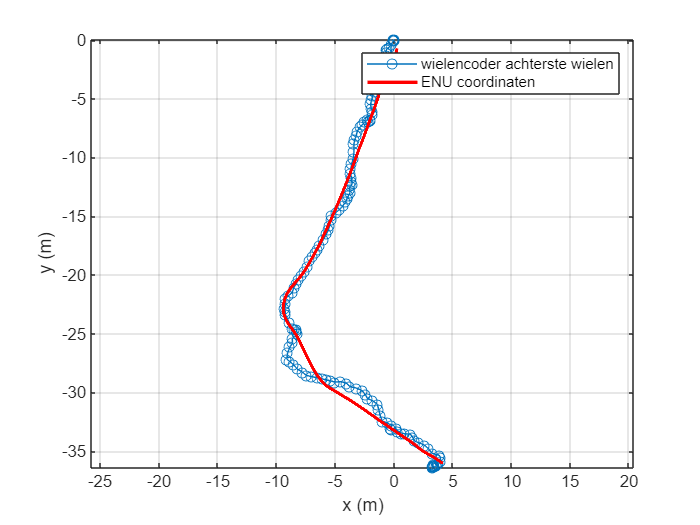

load('encoder_data.mat')
load('gnss_data.mat')

t0=min(encoder_data(1,1),gnss_data(1,1));

gnss_t=gnss_data(:,1)-t0;
lat=gnss_data(:,2)*180/pi;
lon=gnss_data(:,3)*180/pi;
height=gnss_data(:,4);

wgs84 = wgs84Ellipsoid('meter');
[gnss_x,gnss_y] = geodetic2enu(lat,lon,height,lat(1),lon(1),height(1),wgs84);

gnss_pos=[gnss_x gnss_y];
encoder_t=encoder_data(:,1)-t0;

t_start=max(encoder_t(1),gnss_t(1));
t_end=min(encoder_t(end),gnss_t(end));

gnss_ind=find(gnss_t>=t_start,1,"first"):find(gnss_t<=t_end,1,"last");

x=[0.225 0.225 1.465 0 0 0];

e=@(x) sqrt(mean(sum((interp1(encoder_t,calcOdom(encoder_data(:,4:5),x),gnss_t(gnss_ind),"linear")-gnss_pos(gnss_ind,:)).^2,2)));

options = optimset('MaxIter',inf,'MaxFunEvals',inf,'TolFun',1e-9,'TolX',1e-9);
x=fminsearch(e,x,options);

odom_pos=calcOdom(encoder_data(:,4:5),x);
plot(gnss_x,gnss_y, 'o-')
hold on
axis equal
plot(odom_pos(:,1),odom_pos(:,2), 'r', LineWidth=2)
grid on
xlabel("x (m)", 'FontSize', 11)
ylabel("y (m)", 'FontSize', 11)
hold off
legend(["wielencoder achterste wielen","ENU coordinaten"])

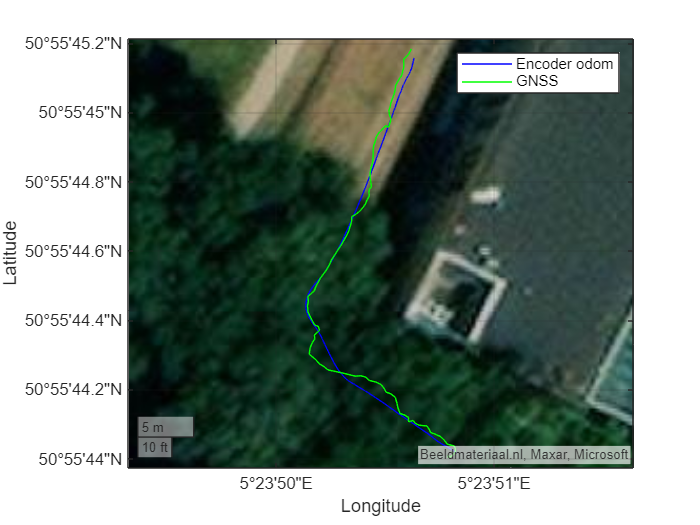

[odom_lat,odom_lon]=enu2geodetic(odom_pos(:,1),odom_pos(:,2),zeros(length(odom_pos),1),lat(1),lon(1),0,wgs84);
geoplot(odom_lat,odom_lon,"Color",'blue')
hold on
geoplot(lat,lon,"Color",'green')
hold off
geobasemap satellite
legend(["Encoder odom","GNSS"])


function pos=calcOdom(encoder_data,x)
wheel_rad=x(1:2);
wheel_dist=x(3);
theta0=x(4);
pos0=x(5:6);

wheel_pos=encoder_data.*wheel_rad.*[1 -1]*2*pi/1952;
delta_wheel_pos=diff(wheel_pos);
delta_pos=mean(delta_wheel_pos,2);
delta_theta=(delta_wheel_pos(:,2)-delta_wheel_pos(:,1))/wheel_dist;

theta=[0;cumsum(delta_theta(1:end-1))]+theta0;
delta_pos_xy=delta_pos.*[cos(theta) sin(theta)];
pos=[0 0;cumsum(delta_pos_xy)]+pos0;
end